# 部分空間の上への射影と最小2乗近似

## 最小2乗解

1つの未知数をもつ問題$\mathit{ax}=b$の最小2乗解は


$$\overline{x} =\frac{a^T b}{a^T a}$$


である。

幾何学的には、この解は$a$を通る直線上の、$b$に最も近い点、$p=\overline{x} a$と同一

## 3.2.1

mean([150,153,150,151])

ans = 151

## 3.2.2

clear
a = [3,4]

a =        3              4       


b = [10,5]

b =       10              5       


dot(a,b)/dot(a,a)

ans =        2       


## 多変数の最小2乗問題


$$\mathit{Ax}=b$$


この時、誤差ベクトル$E$は


$$E=\left\|\mathit{Ax}-b\right\|$$


となり、これを最小とする最小2乗解は列空間内の$b$にもっとも近い点$p=A\overline{x}$の位置を求めることと同義

また、**誤差ベクトルはその部分空間に直角でなければならない**

まとめると

- 対象となる部分空間は、$A$**の列空間**である。

- 誤差ベクトル$b-A\hat{x}$は**その列空間に直交する**。

- つまり、$b-A\hat{x}$は$A^T$の零空間に存在する⇒$A^T \left(b-A\hat{x} \right)=0$

## 正規方程式


$$A^T A\hat{x} =A^T b$$


もし、$A$の列が線形独立（可逆）ならば、


$$\hat{x} ={\left(A^T A\right)}^{-1} A^T b$$


よって


$$p=A\hat{x} ={A\left(A^T A\right)}^{-1} A^T b$$


## 3.2.3

clear
A = [1,0;0,1;1,1]

A =        1              0       
       0              1       
       1              1       


b = [1;1;0]

b =        1       
       1       
       0       


t1 = A'*A

t1 =        2              1       
       1              2       


t2 = t1^-1 * A'

t2 =        2/3           -1/3            1/3     
      -1/3            2/3            1/3     


t2 * b

ans =        1/3     
       1/3     


A = [1;1;1]

A =        1       
       1       
       1       


b = [1;3;5]

b =        1       
       3       
       5       


t1 = A'*A

t1 =        3       


t2 = t1^-1 * A'

t2 =        1/3            1/3            1/3     


t2 * b

ans =        3       


## 3.2.4

clear
A = [1,0;0,1;1,1]

A =        1              0       
       0              1       
       1              1       


b = [1;3;4]

b =        1       
       3       
       4       


syms u v
x = [u;v]

$$x = \left(\begin{array}{c} u\\ v \end{array}\right)$$

norm(A*x-b)^2

$$ans = {\left|u-1\right|}^{2}+{\left|v-3\right|}^{2}+{\left|u+v-4\right|}^{2}$$


$$\begin{array}{l}
\frac{{dE}^2 }{du}=4u−10+2v=0\\
\frac{{dE}^2 }{dv}=4v−14+2u=0\\
u=1\\
v=3
\end{array}$$


T = A'*A

T =      2     1
     1     2


A'*b

ans =      5
     7



$$\left\lbrack \begin{array}{c}
2 & 1\\
1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
v
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
5\\
7
\end{array}\right\rbrack$$


p = A * [1;3]

p =      1
     3
     4


$p=b$なので、pは列空間内に存在する

## 射影行列


$$P={A\left(A^T A\right)}^{−1} A^T$$


基本性質

(1)べき等$P^2 =P$

(2)対称$P=P^T$

## 3.2.5

u1 = [1;1;0]

u1 =        1       
       1       
       0       


u2 = [1;0;1]

u2 =        1       
       0       
       1       


b = [0;2;1]

b =        0       
       2       
       1       


A = [u1,u2]

A =        1              1       
       1              0       
       0              1       


P = A*(A'*A)^-1*A'

P =        2/3            1/3            1/3     
       1/3            2/3           -1/3     
       1/3           -1/3            2/3     


p = P * b

p =        1       
       1       
       0       


pin = b - P * b

pin =       -1       
       1       
       1       


x = (A'*A)^-1*A'*b

x =        1       
       0       


## 3.2.6


$${\left(I−P\right)}^2 =I^2 −\mathit{IP}−\mathit{PI}+P^2 =I−2P+P^2 =I−P$$



$${\left(I−P\right)}^T =I^T −P^T =I−P$$



$$\begin{array}{l}
P^2 ={\left(P_1 +P_2 \right)}^2 =P_1^2 +P_2^2 =P_1 +P_2 \\
P^T ={\left(P_1 +P_2 \right)}^T =P_1^T +P_2^T =P_1 +P_2 
\end{array}$$


## 3.2.7


$$\begin{array}{l}
H^2 ={\left(I-2P\right)}^2 \\
=I-4P+4P^2 \\
=I
\end{array}$$


## 3.2.8


$$P^2 ={\left({\mathit{uu}}^T \right)}^2 ={\mathit{uu}}^T {\mathit{uu}}^T ={\mathit{uu}}^T =P$$



$$P^T ={\left({\mathit{uu}}^T \right)}^T ={\left(u^T \right)}^T u^T ={\mathit{uu}}^T$$


## 3.2.9


$$P\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
y
\end{array}\right\rbrack$$


となる射影行列Pを探せばよいので


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
0 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
y
\end{array}\right\rbrack \\
P^2 =P\\
P^T =P
\end{array}$$


## データの最小2乗近似

## 例


$$\begin{array}{l}
t=0,y=0\\
t=1,y=1\\
t=3,y=2\\
t=4,y=5
\end{array}$$


が与えられた場合の優決定系$\mathit{Ax}=b$は


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
1 & 0\\
1 & 1\\
1 & 3\\
1 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C\\
D
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
2\\
5
\end{array}\right\rbrack \\
A^T A=\left\lbrack \begin{array}{c}
4 & 8\\
8 & 26
\end{array}\right\rbrack \\
{\left(A^T A\right)}^{-1} =\frac{1}{20}\left\lbrack \begin{array}{c}
13 & -4\\
-4 & 2
\end{array}\right\rbrack 
\end{array}$$



$$\overline{x} ={\left\lbrack \begin{array}{c}
\overline{C} \\
\overline{D} 
\end{array}\right\rbrack =\left(A^T A\right)}^{-1} A^T b=\frac{1}{20}\left\lbrack \begin{array}{c}
13 & -4\\
-4 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1 & 1 & 1 & 1\\
0 & 1 & 3 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1\\
2\\
5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{2}{10}\\
\frac{11}{10}
\end{array}\right\rbrack$$


よってこのデータに対する最良の直線は


$$y=-\frac{2}{10}+\frac{11}{10}t$$


## 3.2.10


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
1\\
1\\
\vdots \\
1
\end{array}\right\rbrack \left\lbrack C\right\rbrack =\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_m 
\end{array}\right\rbrack \\
{\left(A^T A\right)}^{-1} =\frac{1}{m}\\
\frac{1}{m}\left\lbrack \begin{array}{c}
1 & 1 & \cdots  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_m 
\end{array}\right\rbrack =\frac{y_1 +\cdots +y_m }{m}
\end{array}$$


## 3.2.11

A = [1,-1;1,0;1,1;1,2]

A =        1             -1       
       1              0       
       1              1       
       1              2       


b = [2;0;-3;-5]

b =        2       
       0       
      -3       
      -5       


x = (A'*A)^-1*A'*b

x =       -3/10    
     -12/5     


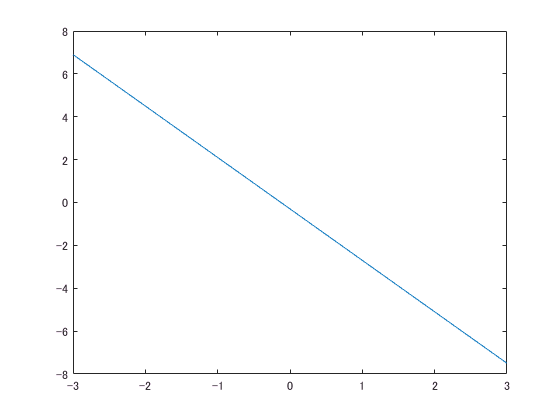

t = -3:3;
y = x(1) + x(2) * t;
plot(t,y)

## 3.2.12


$$\begin{array}{l}
A=\left\lbrack \begin{array}{c}
1 & -1 & 1\\
1 & 0 & 0\\
1 & 1 & 1\\
1 & 2 & 4
\end{array}\right\rbrack \\
x=\left\lbrack \begin{array}{c}
C\\
D\\
E
\end{array}\right\rbrack \\
b=\left\lbrack \begin{array}{c}
2\\
0\\
-3\\
-5
\end{array}\right\rbrack 
\end{array}$$
